## Modelar o sistema 

entrada ->  0 - 255

saida - > 0 - 1023

tensao -> 0 - 5v

### Planta do sistema de primeira ordem


$$G_p(s) = \frac{a}{s+a}$$


###  Identificar especificações de desempenho

dados = readtable('./Remodelando/saida-156.csv');
dados.Saida = dados.Saida;

dados

dados = 371×2 table
      Tempo       Saida
    __________    _____

           128       0 
          8108       0 
         15964       0 
         23876      11 
         31840      34 
         39792      66 
         47752     104 
         55772     150 
         63788     193 
         71804     234 
         79812     269 
         87828     297 
         95848     323 
    1.0386e+05     351 
    1.1192e+05     375 
    1.1999e+05     396 



t8ms = 1:length(dados.Tempo);
t8ms = t8ms * 8e-3;

#### Especificações de desempenho

info = stepinfo(dados.Saida, t8ms);

% Tempo de acomodação a 2%
Ts = info.SettlingTime;
Tr = info.RiseTime;
fprintf('Tempo de subida : %.4f s\n', Tr);

Tempo de subida : 0.1713 s


fprintf('Tempo de acomodação: %.4f s\n', Ts);

Tempo de acomodação: 0.3496 s


- Constante de tempo


$$a = \frac{1}{\tau} ; C(\tau) = 0,63C_f $$


Cf = dados.Saida(end)

Cf = 595

Ct = 0.63 * Cf

Ct = 374.8500

idx_tau = find(dados.Saida >= Ct, 1)  % índice do tempo correspondente

idx_tau = 15

tau = t8ms(idx_tau)          % constante de tempo estimada

tau = 0.1200

a_tau = (1/tau)

a_tau = 8.3333

- Tempo de subida


$$T_r = \frac{2,2}{a}$$


a_tr = Tr / 2

a_tr = 0.0857

- Tempo de acomodação


$$T_s = \frac{4}{a}$$


a_ts = Ts / 2

a_ts = 0.1748


a_tau * 1.25

ans = 10.4167

### Modelo do sistema

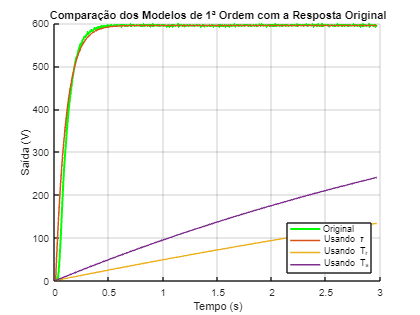

a_valores = [a_tau * 1.25, a_tr, a_ts];
rotulos   = {'Usando \tau', 'Usando T_r', 'Usando T_s'};

% Modelo base
s = tf('s');
K = Cf;  % ganho final do sistema

% Figura
f = figure;
hold on;
plot(t8ms, dados.Saida, 'k', 'LineWidth', 2, 'DisplayName', 'Original', Color='g');

% Loop pelos modelos
for i = 1:length(a_valores)
    a = a_valores(i);
    Gp = a * K / (s + a);
    [y_modelo, tOut] = step(Gp, t8ms);
    plot(t8ms, y_modelo, 'LineWidth', 1.5, 'DisplayName', rotulos{i});
end

title('Comparação dos Modelos de 1ª Ordem com a Resposta Original');
xlabel('Tempo (s)');
ylabel('Saída (V)');
grid on;
legend('Location', 'southeast');
hold off;

exportgraphics(f, './Resultados/Modelo.pdf', 'ContentType', 'vector');